# COTS Ensemble Live Script 23

## Set Interpreter

setInterpLatex()

## Contents

Distance-based Connectivity Comparison

Network theory metrics - maximum values

Extra network theory metrics

## Assumptions

## Network theory metrics - maximum values

% need to now form yearly global matrices
conMatGlobYearly = cell(1, 5);
for i = 1:length(conMatsSeasSlim)
    conMatGlobYearly{i} = zeros(nReefs, nReefs);
    if i == 5
        conMatGlobYearly{i} = (conMatsSeasGbrlDp{5} ...
            + conMatsSeasGbrlUp{5} + conMatsSeasSlim{5}) / 3;
        continue
    end
    conMatGlobYearly{i} = (conMatsSeasGbrlDp{i} ...
            + conMatsSeasGbrlUp{i} + conMatsSeasSlim{i} ...
            + conMatsSeasGbr1{i}) / 4;
    conMatGlobYearly{i} = sparse(conMatGlobYearly{i});
end

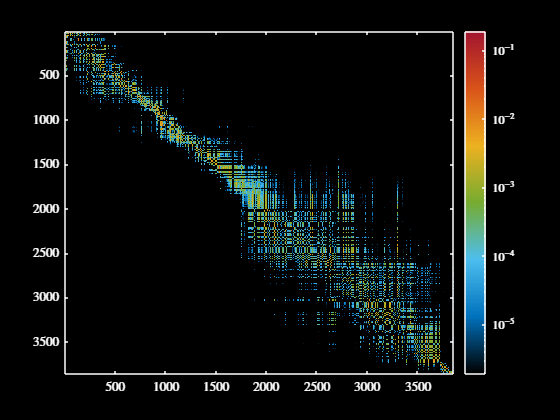

% let's make sure they look normal
figure
for i = 1:5
    clf
    imagesc(conMatGlobYearly{i}(sortLat3861, sortLat3861))
    colormap(myColourMap())
    set(gca, 'colorscale', 'log')
    colorbar()
    darkFig()
    saveFig("fig" + i)
end

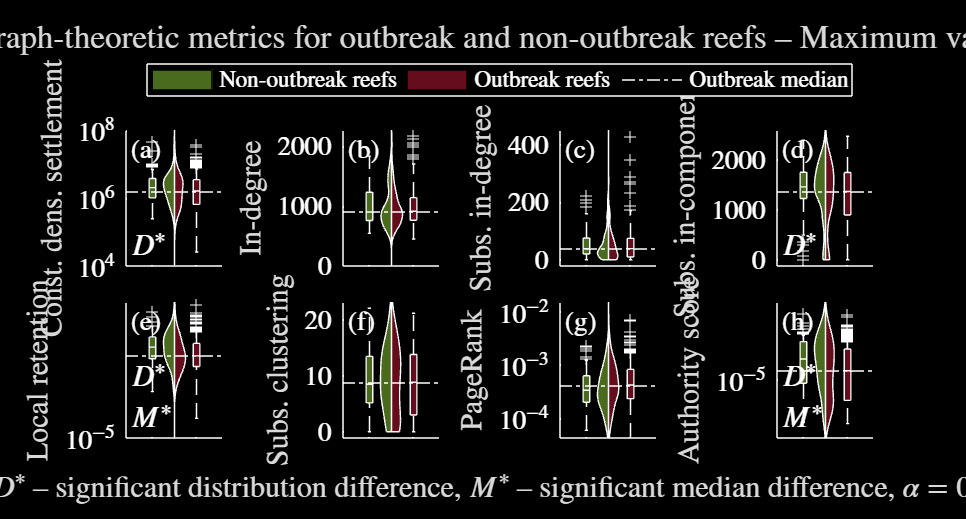

Const. dens. settlement
Mean non-outbreaks: 

ans = 3.2605e+06

Mean outbreaks: 

ans = 2.7956e+06

KS test

p = 0.0422

Median test

p = 0.1385

--------------------------------------------------
In-degree
Mean non-outbreaks: 

ans = 992.8889

Mean outbreaks: 

ans = 988.9541

KS test

p = 0.6322

Median test

p = 0.7797

--------------------------------------------------
Subs. in-degree
Mean non-outbreaks: 

ans = 54.1889

Mean outbreaks: 

ans = 54.0530

KS test

p = 0.2987

Median test

p = 0.7797

--------------------------------------------------
Subs. in-component
Mean non-outbreaks: 

ans = 1.3688e+03

Mean outbreaks: 

ans = 1.2325e+03

KS test

p = 0.0177

Median test

p = 0.3186

--------------------------------------------------
Local retention
Mean non-outbreaks: 

ans = 0.0072

Mean outbreaks: 

ans = 0.0061

KS test

p = 0.0019

Median test

p = 0.0071

--------------------------------------------------
Subs. clustering
Mean non-outbreaks: 

ans = 9.3669

Mean outbreaks: 

ans = 8.6069

KS test

p = 0.1040

Median test

p = 0.8315

--------------------------------------------------
PageRank
Mean non-outbreaks: 

ans = 4.9635e-04

Mean outbreaks: 

ans = 6.8977e-04

KS test

p = 0.1416

Median test

p = 0.0959

--------------------------------------------------
Authority score
Mean non-outbreaks: 

ans = 0.0012

Mean outbreaks: 

ans = 6.1567e-04

KS test

p = 0.0017

Median test

p = 0.0273

--------------------------------------------------


cotsDensBrt = readtable("../Data/Matlab Transfer/cotsDensBrtV3.csv");
var1 = readtable("../Data/Matlab Transfer/cotsDensKnn.csv");
cotsDensBrt.cotsPerTowMaxImput = var1.cotsPerTowMaxImput;

% let's redo the network theory stuff, but using the maximum values
% temporally
% let's redo figures with different graph-theoretic metrics
var1 = ["", "DM"];
figure
for i = 1:2
    clf()
    plotLarvalSupplyV2(cotsDensBrt, conMatGlobYearly, ...
        nonOutbrReefs, outbrReefs, "Graph-theoretic metrics for " + ...
        "outbreak and non-outbreak reefs -- Maximum values", ...
        i == 2, false, "conMax")
    saveFig("graphTheoryMetricsMax" + var1(i))
end

## Extra network theory metrics

% let's just screw around with a random network rq, or like a subset of the
% global connectivity matrix might be better

% want to look at some additional network theoretic metrics that I could
% add in
reefInds = 1:100:1000;
var1 = full(conMatGlobal(reefInds, reefInds))

var1 =     0.0047    0.0000    0.0000    0.0001    0.0000         0         0         0         0         0
    0.0000    0.0007    0.0000         0    0.0000    0.0000         0         0         0         0
    0.0000    0.0000    0.0073    0.0000    0.0001    0.0000    0.0000         0         0         0
    0.0000    0.0000    0.0000    0.0072    0.0000    0.0000    0.0000         0         0         0
         0    0.0000    0.0042         0    0.0002    0.0000    0.0000         0         0         0
    0.0000    0.0000    0.0005    0.0001    0.0000    0.0001    0.0000         0         0    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0065         0         0    0.0000
         0         0         0         0         0         0    0.0000    0.0009    0.0000    0.0001
         0         0         0         0         0         0         0    0.0000    0.0057    0.0001
         0         0    0.0000         0         0    0.0000    0.0000    0.0001    

sum(sum(var1 == 0))

ans = 42


% ok cool

% need to use a digraph if you have weighted edges
var2 = digraph(var1)

var2 =   digraph with properties:

    Edges: [58×2 table]
    Nodes: [10×0 table]



% figure out if it's costly to set up the graphs
tic
digraph(conMatGlobal)

ans =   digraph with properties:

    Edges: [4593564×2 table]
    Nodes: [3861×0 table]


toc

Elapsed time is 0.253783 seconds.


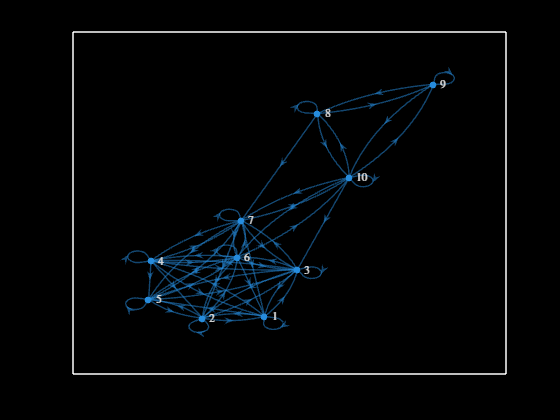


% ok sweet so it's quick to turn the massive matrices into digraphs epic
figure
plot(var2)
darkFig()

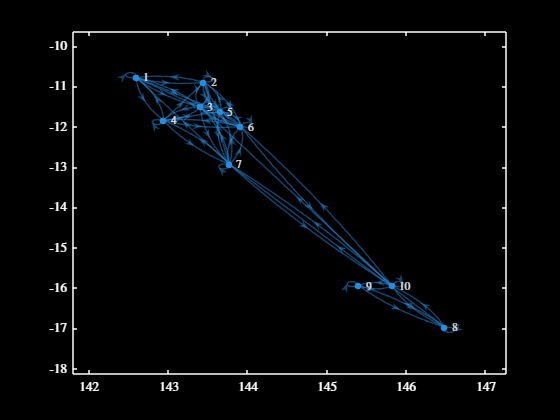

% saveCoolFig("graphImage")

% let's do another plot of the actual spatial location
figure
plot(var2, 'XData', centroidsLL(reefInds, 1), 'YData', ...
    centroidsLL(reefInds, 2))
darkFig()


% let's make sure that the links are correct I suppose
var2.Edges

ans = 58×2 table
    EndNodes      Weight  
    ________    __________

     1    1       0.004693
     1    2     9.8289e-09
     1    3     1.0861e-05
     1    4     8.7126e-05
     1    5     1.4253e-08
     2    1     6.1636e-06
     2    2     0.00069024
     2    3     2.4305e-06
     2    5      3.354e-06
     2    6     2.9828e-09
     3    1     4.9605e-07
     3    2     4.8737e-05
     3    3      0.0073242
     3    4     1.4205e-09
     3    5     0.00013402
     3    6     6.9871e-07


var1(1, 1)

ans = 0.0047

var1(1, 5)

ans = 1.4253e-08

var1(2, 3)

ans = 2.4305e-06

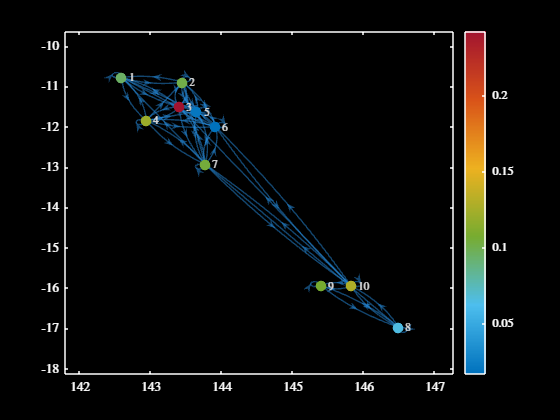


% alright, looks good, let's try calculate a few different metrics just for
% fun an eyeball them
var3 = centrality(var2, 'pagerank', 'Importance', var2.Edges.Weight);
figure
p = plot(var2, 'XData', centroidsLL(reefInds, 1), 'YData', ...
    centroidsLL(reefInds, 2), 'MarkerSize', 7);
p.NodeCData = var3;
colormap(myColourMap("dmTurbo"))
colorbar()
darkFig()

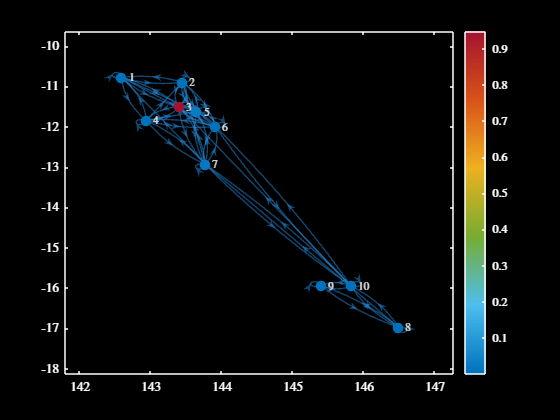


% let's also do authorities
var3 = centrality(var2, 'authorities', 'Importance', var2.Edges.Weight);
figure
p = plot(var2, 'XData', centroidsLL(reefInds, 1), 'YData', ...
    centroidsLL(reefInds, 2), 'MarkerSize', 7);
p.NodeCData = var3;
colormap(myColourMap("dmTurbo"))
colorbar()
darkFig()

sum(var3)

ans = 1.0000

sum(var1, 2)

ans =     0.0048
    0.0007
    0.0075
    0.0072
    0.0045
    0.0007
    0.0066
    0.0010
    0.0058
    0.0076


sum(var1, 1)

ans =     0.0047    0.0008    0.0121    0.0074    0.0004    0.0001    0.0066    0.0010    0.0059    0.0076


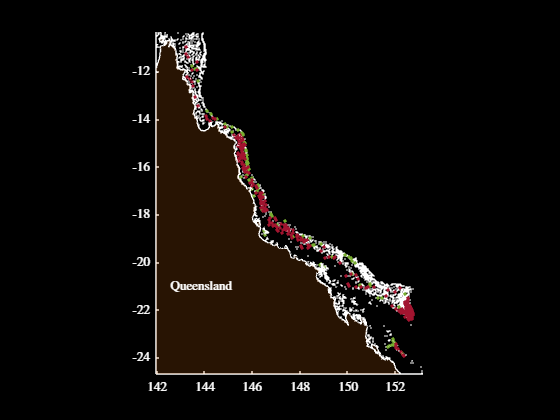

% let's look at the spatial distribution of the outbreak and non-outbreak
% reefs
figure
figResize(1.65 * 1, 1.65 * 0.4)
hold on
theta = -35 * pi / 180;
var1 = [cos(theta), -sin(theta); sin(theta), cos(theta)];
var2 = (var1 * centroidsLL')';
plot(var2(:, 1), var2(:, 2), '.', 'color', ...
    [0.2, 0.2, 0.2], 'MarkerSize', 1)
plot(var2(outbrReefs, 1), var2(outbrReefs, 2), '.', ...
    'color', getColour('k'), 'MarkerSize', 7.75)
plot(var2(outbrReefs, 1), var2(outbrReefs, 2), '.', ...
    'color', getColour('r'), 'MarkerSize', 7)
plot(var2(nonOutbrReefs, 1), var2(nonOutbrReefs, 2), '.', ...
    'color', getColour('k'), 'MarkerSize', 7.75)
plot(var2(nonOutbrReefs, 1), var2(nonOutbrReefs, 2), '.', ...
    'color', getColour('g'), 'MarkerSize', 7)
axis equal
xticks([])
yticks([])
box on
axisLims = axis();
var2 = qldOutline;
var3 = (var1 * [var2.X, var2.Y]')';
var2.X = var3(:, 1);
var2.Y = var3(:, 2);
plotQldOutline(var2, true, false)
axis(axisLims)
xlim([108, 116])
legend(sprintf("Insufficient\ndata"), "", "Outbreak", "", ...
    sprintf("No outbreak"), 'Location', 'best')
title(["Distribution of", "outbreaking and", "non-outbreaking reefs"])
setFontSize(12)
text(111, -98, ["$\,\uparrow$", "N"], 'Rotation', -35, 'color', 'k', ...
    'fontsize', 16)
lightFig()
saveFig("outbreaksSpatially")
darkFig()
saveFig("outbreaksSpatiallyDM")


% let's figure out how many are in the initiation box
sum((centroidsLL(nonOutbrReefs, 2) > -16) ...
    .* (centroidsLL(nonOutbrReefs, 2) < -14.5) == 1)

ans = 16

sum((centroidsLL(outbrReefs, 2) > -16) ...
    .* (centroidsLL(outbrReefs, 2) < -14.5) == 1)

ans = 55


% alright - too few in my opinion to analyse the initation box

% redoing the boxplot figures from before, but gonna see if we can get in a
% kde next to each boxplot lmao

% need to now do the larval settlement one
% alright let's do the final one, where I'm using the brt for both mean and
% median, and then the knn for the maximum
cotsDensBrt = readtable("../Data/Matlab Transfer/cotsDensBrtV3.csv");
var1 = readtable("../Data/Matlab Transfer/cotsDensKnn.csv");
cotsDensBrt.cotsPerTowMaxImput = var1.cotsPerTowMaxImput;
figure
i = 1

i = 1

var1 = ["", "DM"];
clf()
plotLarvalSupplyV2(cotsDensBrt, conMatGlobal, nonOutbrReefs, ...
    outbrReefs, "Estimated larval settlement to outbreak and " + ...
    "non-outbreak reefs", i == 2, false, "no", true)

cotsPerTowMeanImput
Mean non-outbreaks: 

ans = 4.3363e+05

Mean outbreaks: 

ans = 7.9930e+05

KS test

p = 1.9545e-05

Median test

p = 4.8913e-06

--------------------------------------------------
cotsPerTowMedianImput
Mean non-outbreaks: 

ans = 6.0558e+04

Mean outbreaks: 

ans = 8.9112e+04

KS test

p = 0.0011

Median test

p = 7.8158e-04

--------------------------------------------------
cotsPerTowMaxImput
Mean non-outbreaks: 

ans = 2.5194e+06

Mean outbreaks: 

ans = 5.3534e+06

KS test

p = 2.0788e-09

Median test

p = 7.4900e-09

--------------------------------------------------


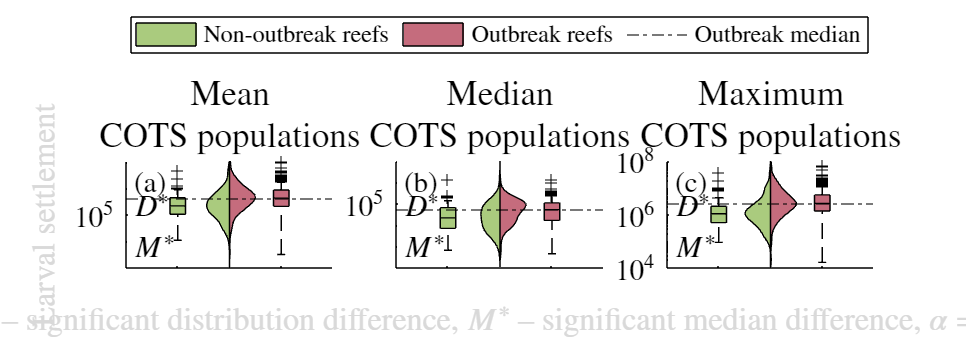

setFontSize(16)

% let's just see if I can make a kde first of all
cotsDensBrt = readtable("../Data/Matlab Transfer/cotsDensBrtV3.csv");
var1 = readtable("../Data/Matlab Transfer/cotsDensKnn.csv");
cotsDensBrt.cotsPerTowMaxImput = var1.cotsPerTowMaxImput;
var5 = ["Mean", "Median", "Max"];
j = 1;
conMetricVals = replaceNaNs(conMatGlobal', 0) * ...
    ((replaceNaNs(cotsDensBrt{:, "cotsPerTow" + var5(j) + ...
    "Imput"}, 0) .* replaceNaNs(cotsDensBrt.area, 0)));
var1 = [conMetricVals(nonOutbrReefs); ...
    conMetricVals(outbrReefs)];
var2 = [zeros(size(conMetricVals(nonOutbrReefs))); ...
    ones(size(conMetricVals(outbrReefs)))];

% now make a kde plot of the data lmao
[y, x] = kde(var1(var2 == 0));
trapz(x, y)

ans = 0.9998

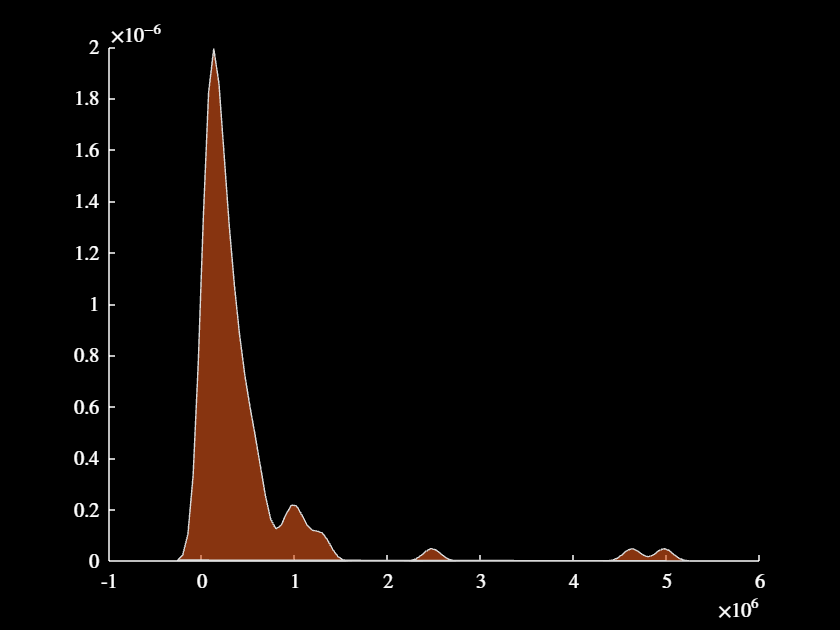

% need to remove the negative points
% y = y(x > 0);
% x = x(x > 0);
% y = [0; y];
% x = [eps; x];
figure
hold on
patch(x, y, getColour(2), 'FaceAlpha', 0.625);

% plot(x, y)
darkFig()

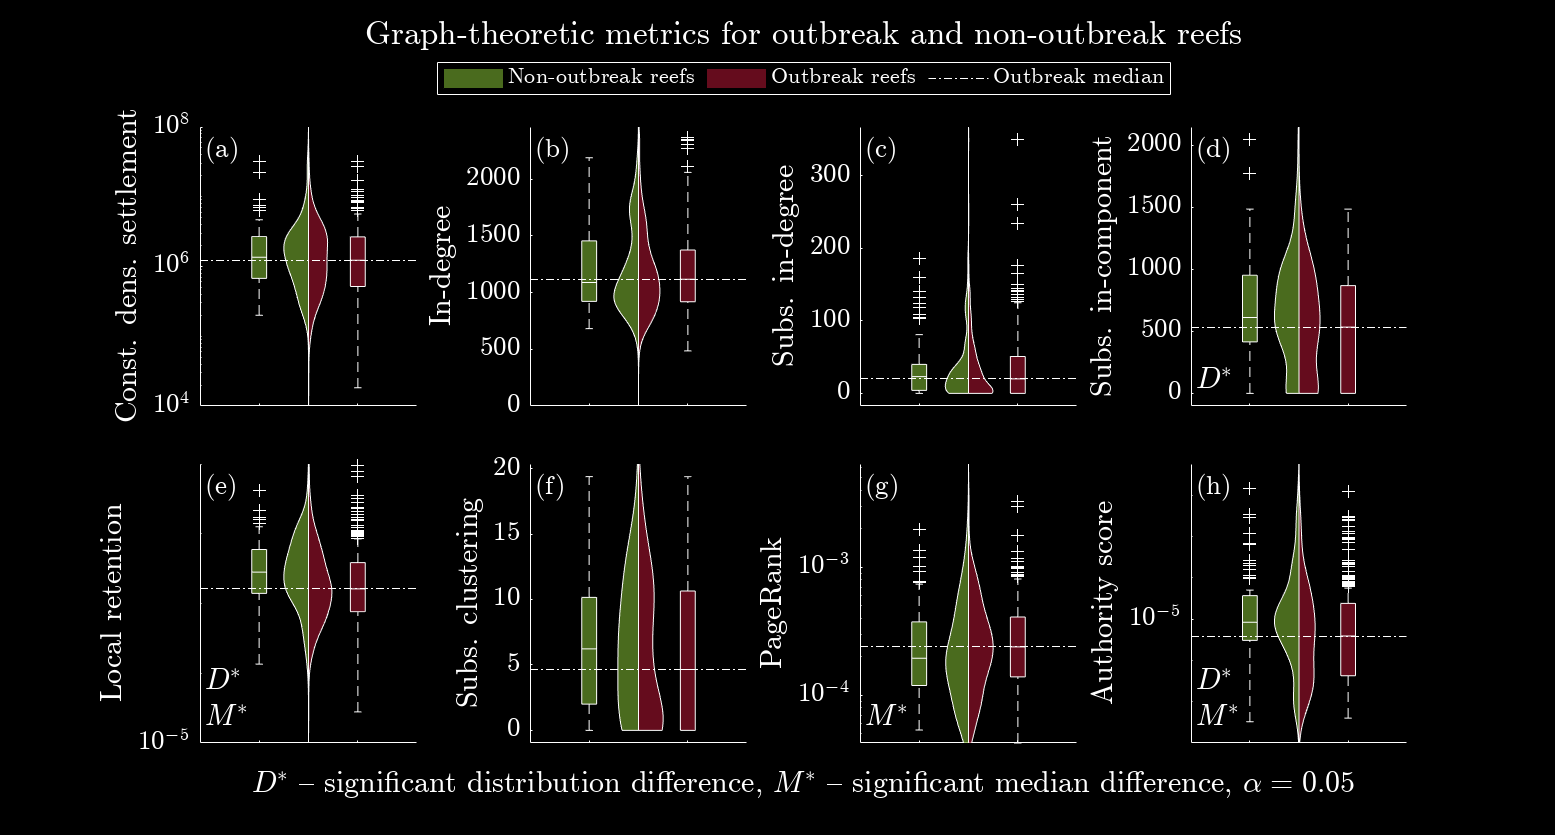

% ok, now let's actually re-run the plots

% let's redo figures with different graph-theoretic metrics
var1 = ["", "DM"];
figure
for i = 1:2
    clf()
    plotLarvalSupplyV2(cotsDensBrt, conMatGlobal, ...
        nonOutbrReefs, outbrReefs, "Graph-theoretic metrics for " + ...
        "outbreak and non-outbreak reefs", ...
        i == 2, false, "con", false, false)
    saveFig("graphTheoryMetrics" + var1(i))
end

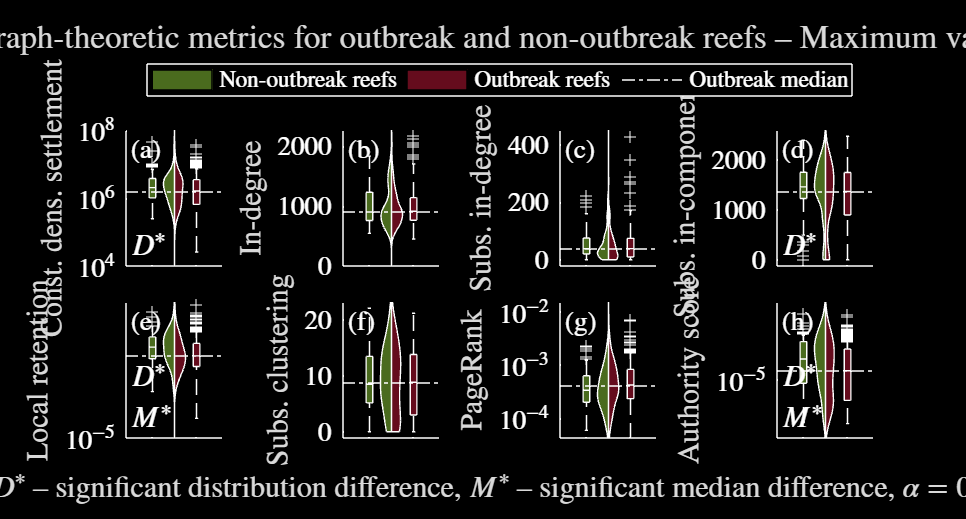

% let's redo the network theory stuff, but using the maximum values
% temporally
% let's redo figures with different graph-theoretic metrics
var1 = ["", "DM"];
figure 
for i = 1:2
    clf()
    plotLarvalSupplyV2(cotsDensBrt, conMatGlobYearly, ...
        nonOutbrReefs, outbrReefs, "Graph-theoretic metrics for " + ...
        "outbreak and non-outbreak reefs -- Maximum values", ...
        i == 2, false, "conMax", false, false)
    saveFig("graphTheoryMetricsMax" + var1(i))
end

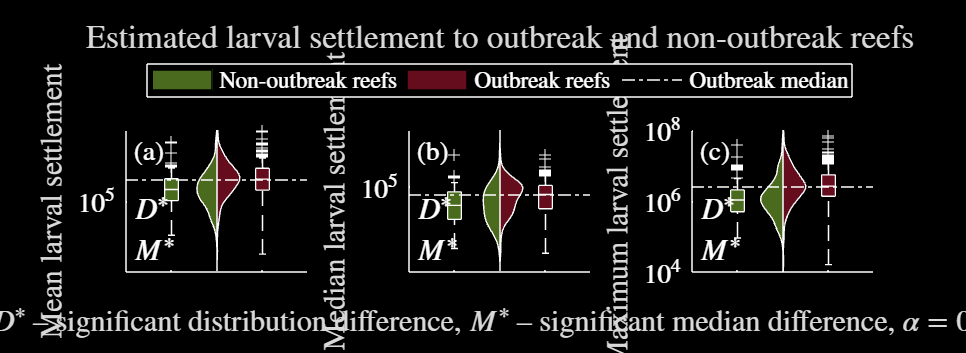

cotsPerTowMeanImput
Mean non-outbreaks: 

ans = 4.3363e+05

Mean outbreaks: 

ans = 7.9930e+05

KS test

p = 1.9545e-05

Median test

p = 4.8913e-06

--------------------------------------------------
cotsPerTowMedianImput
Mean non-outbreaks: 

ans = 6.0558e+04

Mean outbreaks: 

ans = 8.9112e+04

KS test

p = 0.0011

Median test

p = 7.8158e-04

--------------------------------------------------
cotsPerTowMaxImput
Mean non-outbreaks: 

ans = 2.5194e+06

Mean outbreaks: 

ans = 5.3534e+06

KS test

p = 2.0788e-09

Median test

p = 7.4900e-09

--------------------------------------------------


% alright let's do the final one, where I'm using the brt for both mean and
% median, and then the knn for the maximum
cotsDensBrt = readtable("../Data/Matlab Transfer/cotsDensBrtV3.csv");
var1 = readtable("../Data/Matlab Transfer/cotsDensKnn.csv");
cotsDensBrt.cotsPerTowMaxImput = var1.cotsPerTowMaxImput;

% then do the boxplots
figure
figResize(1, 1.75)
var1 = ["", "DM"];
for i = 1:2
    clf()
    plotLarvalSupplyV2(cotsDensBrt, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement to outbreak and " + ...
        "non-outbreak reefs", i == 2, false)
    saveFig("estimatedLarvSupp" + var1(i))
end

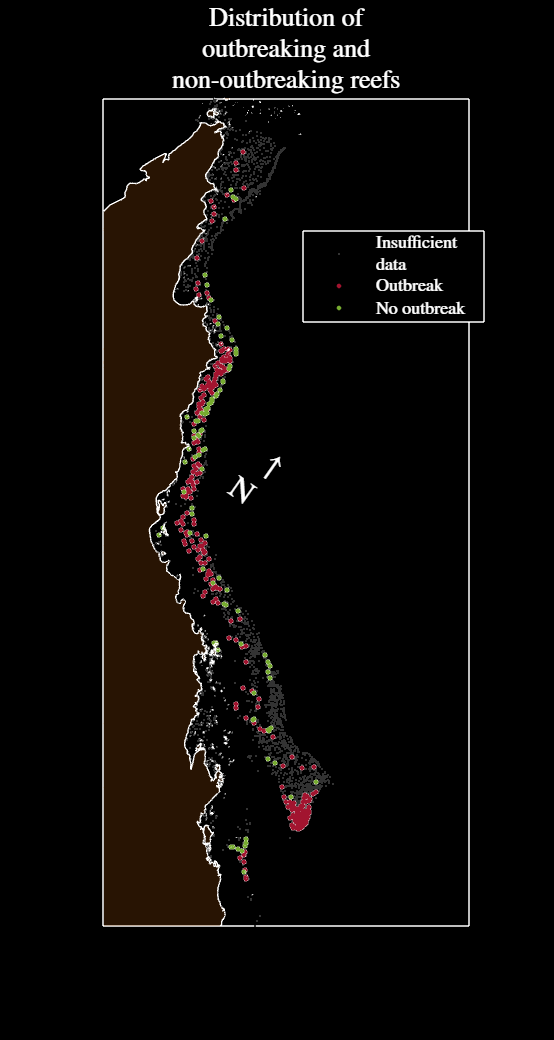

% let's try and make a new figure for the outbreak and non-outbreak reefs

% I guess we can just mask out the nans? and look at the densities of
% outbreaking vs non-outbreaking reefs?

% make a rotation matrix that will rotate them around the origin

% idk, first let's look at the outbreaking vs non-outbreaking reefs
figure
figResize(1.65 * 1, 1.65 * 0.4)
hold on
theta = -35 * pi / 180;
var1 = [cos(theta), -sin(theta); sin(theta), cos(theta)];
var2 = (var1 * centroidsLL')';
plot(var2(:, 1), var2(:, 2), '.', 'color', ...
    [0.2, 0.2, 0.2], 'MarkerSize', 1)
plot(var2(outbrReefs, 1), var2(outbrReefs, 2), '.', ...
    'color', getColour('k'), 'MarkerSize', 7.75)
plot(var2(outbrReefs, 1), var2(outbrReefs, 2), '.', ...
    'color', getColour('r'), 'MarkerSize', 7)
plot(var2(nonOutbrReefs, 1), var2(nonOutbrReefs, 2), '.', ...
    'color', getColour('k'), 'MarkerSize', 7.75)
plot(var2(nonOutbrReefs, 1), var2(nonOutbrReefs, 2), '.', ...
    'color', getColour('g'), 'MarkerSize', 7)
axis equal
xticks([])
yticks([])
box on
axisLims = axis();
var2 = qldOutline;
var3 = (var1 * [var2.X, var2.Y]')';
var2.X = var3(:, 1);
var2.Y = var3(:, 2);
plotQldOutline(var2, true, false)
axis(axisLims)
xlim([108, 116])
legend(sprintf("Insufficient\ndata"), "", "Outbreak", "", ...
    sprintf("No outbreak"), 'Location', 'best')
title(["Distribution of", "outbreaking and", "non-outbreaking reefs"])
setFontSize(12)
text(111, -98, ["$\,\uparrow$", "N"], 'Rotation', -35, 'color', 'k', ...
    'fontsize', 16)
lightFig()
saveFig("outbreaksSpatially")
darkFig()
saveFig("outbreaksSpatiallyDM")

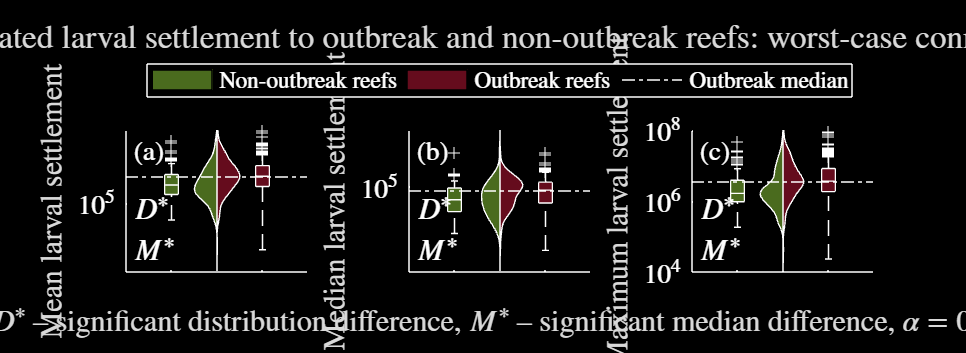

cotsPerTowMeanImput
Mean non-outbreaks: 

ans = 6.6577e+05

Mean outbreaks: 

ans = 1.1287e+06

KS test

p = 1.5296e-05

Median test

p = 1.2139e-04

--------------------------------------------------
cotsPerTowMedianImput
Mean non-outbreaks: 

ans = 8.2876e+04

Mean outbreaks: 

ans = 1.1906e+05

KS test

p = 0.0016

Median test

p = 0.0018

--------------------------------------------------
cotsPerTowMaxImput
Mean non-outbreaks: 

ans = 4.1585e+06

Mean outbreaks: 

ans = 7.7577e+06

KS test

p = 5.3178e-08

Median test

p = 4.3388e-07

--------------------------------------------------


% alright let's do the final one, where I'm using the brt for both mean and
% median, and then the knn for the maximum
cotsDensBrt = readtable("../Data/Matlab Transfer/cotsDensBrtV3.csv");
var1 = readtable("../Data/Matlab Transfer/cotsDensKnn.csv");
cotsDensBrt.cotsPerTowMaxImput = var1.cotsPerTowMaxImput;

% then do the boxplots
figure
figResize(1, 1.75)
var1 = ["", "DM"];
for i = 1:2
    clf()
    plotLarvalSupplyV2(cotsDensBrt, conMatGlobYearly, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement to outbreak and " + ...
        "non-outbreak reefs: worst-case connectivity", i == 2, false)
    saveFig("estimatedLarvSuppMax" + var1(i))
end

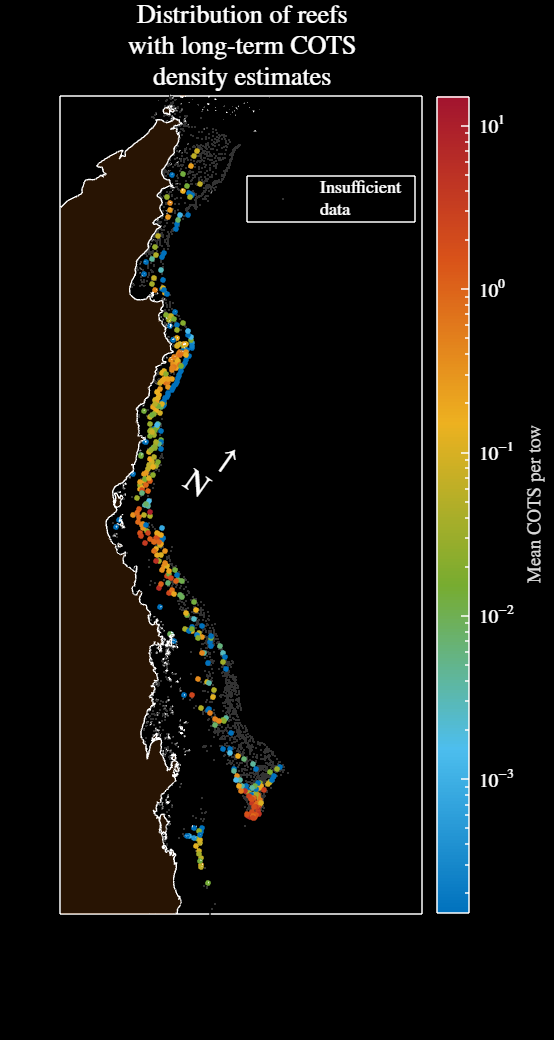

% let's try and make a new figure to show the reefs we have long-term
% population estimates of cots for
cotsDataDens = readtable("../Data/Matlab Transfer/cotsDensData.csv");
figure
figResize(1.65 * 1, 1.65 * 0.4)
hold on
theta = -35 * pi / 180;
var1 = [cos(theta), -sin(theta); sin(theta), cos(theta)];
var2 = (var1 * centroidsLL')';
plot(var2(:, 1), var2(:, 2), '.', 'color', ...
    [0.2, 0.2, 0.2], 'MarkerSize', 1)
cotsDataDens = cotsDataDens( ...
    ~isnan(cotsDataDens.cotsPerTowMean), :);
centroidsData = [cotsDataDens.x, cotsDataDens.y];
var2 = (var1 * centroidsData')';
colormap(myColourMap("dmTurbo"))
scatter(var2(:, 1), var2(:, 2), 8, cotsDataDens.cotsPerTowMean, ...
    'filled')
set(gca,'ColorScale','log')
cBar = colorbar();
cBar.Label.String = "Mean COTS per tow";
cBar.Label.Interpreter = "Latex";
axis equal
xticks([])
yticks([])
box on
axisLims = axis();
var2 = qldOutline;
var3 = (var1 * [var2.X, var2.Y]')';
var2.X = var3(:, 1);
var2.Y = var3(:, 2);
plotQldOutline(var2, true, false)
axis(axisLims)
xlim([108, 116])
legend(sprintf("Insufficient\ndata"), 'Location', 'best')
title(["Distribution of reefs", "with long-term COTS", "density estimates"])
setFontSize(12)
text(111, -98, ["$\,\uparrow$", "N"], 'Rotation', -35, 'color', 'k', ...
    'fontsize', 16)
lightFig()
saveFig("densDataSpatially")
darkFig()
saveFig("densDataSpatiallyDM")